% Define the data for lower limit, upper limit, and frequency
lowerLimits = [30,32,34,36,38,40,42,44,46,48]; 
upperLimits = [32,34,36,38,40,42,44,46,48,50]; 
frequencies = [3,8,24,31,50,61,38,21,12,2];  

% Create a table in MATLAB
dataTable = table(lowerLimits', upperLimits', frequencies',...
    'VariableNames', {'LowerLimit', 'UpperLimit', 'Frequency'});

% Display the table
disp(dataTable);

    LowerLimit    UpperLimit    Frequency
    __________    __________    _________

        30            32            3    
        32            34            8    
        34            36           24    
        36            38           31    
        38            40           50    
        40            42           61    
        42            44           38    
        44            46           21    
        46            48           12    
        48            50            2    




% Calculate mean, median, mode, and standard deviation
data = [];
for i = 1:length(lowerLimits)
    data = [data, ones(1, frequencies(i)) * ((upperLimits(i) + lowerLimits(i)) / 2)];
end

meanValue = mean(data);
medianValue = median(data);
modeValue = mode(data);
stdDeviation = std(data);

% Calculate empirical_mode, mode_shift, and Karl
empirical_mode = 3 * medianValue - 2 * meanValue;
mode_shift = modeValue - empirical_mode;
Karl = (meanValue - modeValue) / stdDeviation;

% Display the calculated statistics
fprintf('Mean: %.2f\n', meanValue);

Mean: 40.14


fprintf('Median: %.2f\n', medianValue);

Median: 41.00


fprintf('Mode: %.2f\n', modeValue);

Mode: 41.00


fprintf('Standard Deviation: %.2f\n', stdDeviation);

Standard Deviation: 3.61


fprintf('Empirical Mode: %.2f\n', empirical_mode);

Empirical Mode: 42.71


fprintf('Mode Shift: %.2f\n', mode_shift);

Mode Shift: -1.71


fprintf('Karl: %.2f\n', Karl);

Karl: -0.24


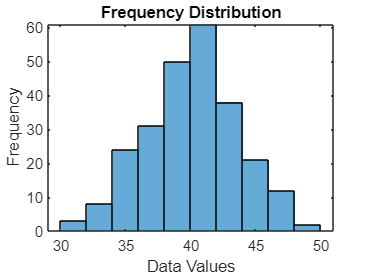


% Plotting the line graph
figure;
histogram(data, 'BinWidth', 2); % Change the 'BinWidth' according to your preference
title('Frequency Distribution');
xlabel('Data Values');
ylabel('Frequency');